## Load LSTM NET from file

clear;
matNetPath = fullfile("models", "LSTM", "Zone8", "LSTM_Zone8_RMSE74.4_20260908_2322.mat");
matNetFile = load(matNetPath);
fprintf("Loaded net from path: %s", matNetPath);

Loaded net from path: models/LSTM/Zone8/LSTM_Zone8_RMSE74.4_20260908_2322.mat

## Model card

[~, modelFileName] = fileparts(matNetPath);

[~, fileName] = fileparts(matNetPath);
tokens = regexp(fileName, 'LSTM_Zone(\d+)_RMSE([\d.]+)_(\d{8}_\d{4})', 'tokens', 'once');
if ~isempty(tokens)
    figTitle = sprintf("LSTM - Zone %s | RMSE %s kWh", tokens{1}, tokens{2});
    zoneStr = tokens{1};
else
    figTitle = strrep(fileName, "_", " ");
    zoneStr = "Unknown";
end

numPredictors = numel(matNetFile.predictorNames);
numLearnables = sum(cellfun(@numel, matNetFile.LSTMnet.Learnables.Value));
metadataTable = table( ...
    ["Zone ID"; "Lookback Window"; "Input Channels"; "LSTM Hidden Units"; "Total Parameters"; "Saved Test RMSE"], ...
    [zoneStr; "48 steps (24 hours)"; sprintf("%d features", numPredictors); "64 units"; sprintf("%d learnables", numLearnables); sprintf("%.2f kWh", matNetFile.testRMSE)], ...
    VariableNames=["Hyperparameter", "Specification"]);
fprintf("Model Metadata Card:")

Model Metadata Card:

disp(metadataTable)

      Hyperparameter           Specification    
    ___________________    _____________________

    "Zone ID"              "8"                  
    "Lookback Window"      "48 steps (24 hours)"
    "Input Channels"       "5 features"         
    "LSTM Hidden Units"    "64 units"           
    "Total Parameters"     "17985 learnables"   
    "Saved Test RMSE"      "74.40 kWh"          



fprintf("Configured Predictors:")

Configured Predictors:

disp(matNetFile.predictorNames')

    "AAC_energy"
    "temp"
    "windspeed"
    "cosHour"
    "sinHour"



## Net properties

Extract figure title from file name

Plot network architecture

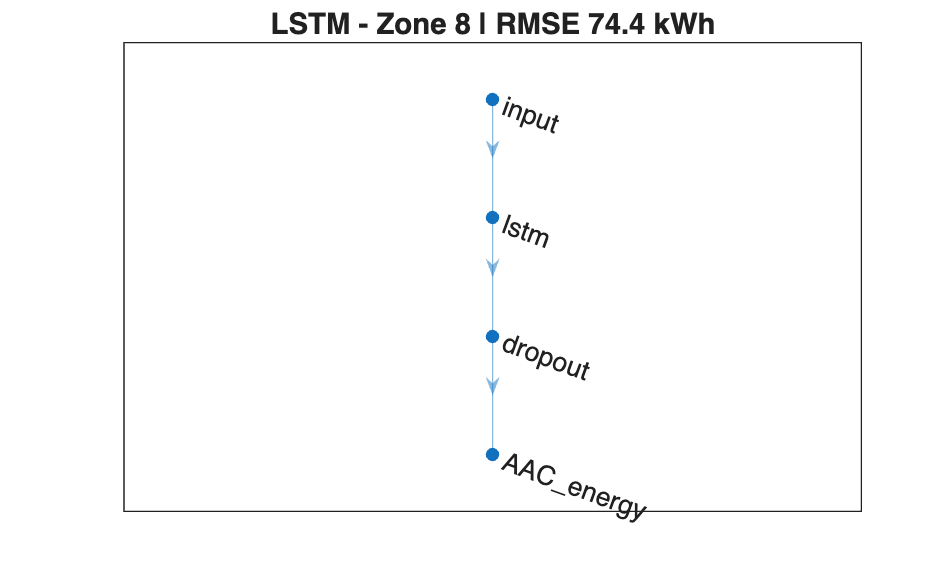

figure
plot(matNetFile.LSTMnet)
title(figTitle, Interpreter="none")

Display learnables table with layer names and tensor dimensions

disp(matNetFile.LSTMnet.Learnables)

       Layer            Parameter              Value      
    ____________    __________________    ________________

    "lstm"          "InputWeights"        {256×5  dlarray}
    "lstm"          "RecurrentWeights"    {256×64 dlarray}
    "lstm"          "Bias"                {256×1  dlarray}
    "AAC_energy"    "Weights"             {  1×64 dlarray}
    "AAC_energy"    "Bias"                {  1×1  dlarray}



Display overall parameter count and input channels

summary(matNetFile.LSTMnet)


   Initialized: true

   Number of learnables: 18k

   Inputs:
      1   'input'   Sequence input with 5 channels



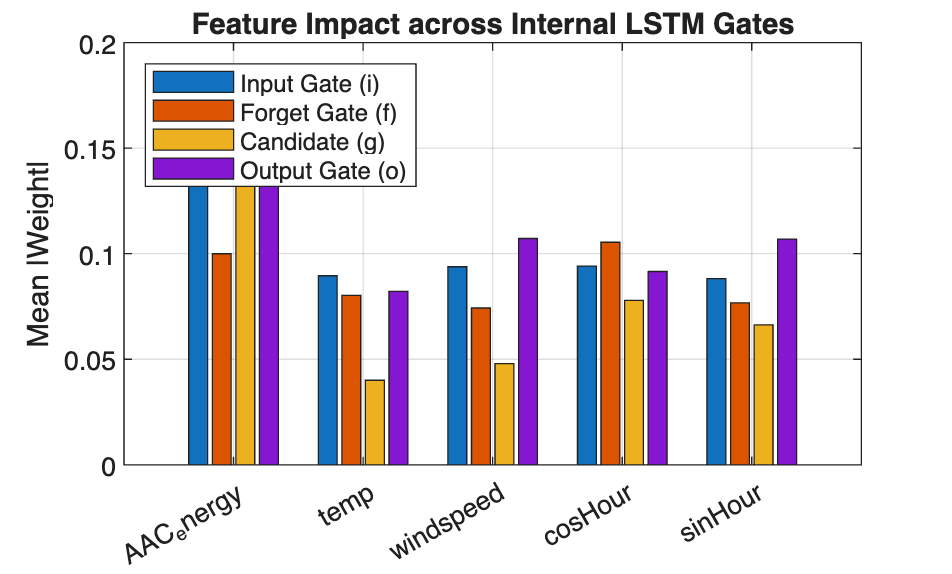

analyzeNetwork(matNetFile.LSTMnet)

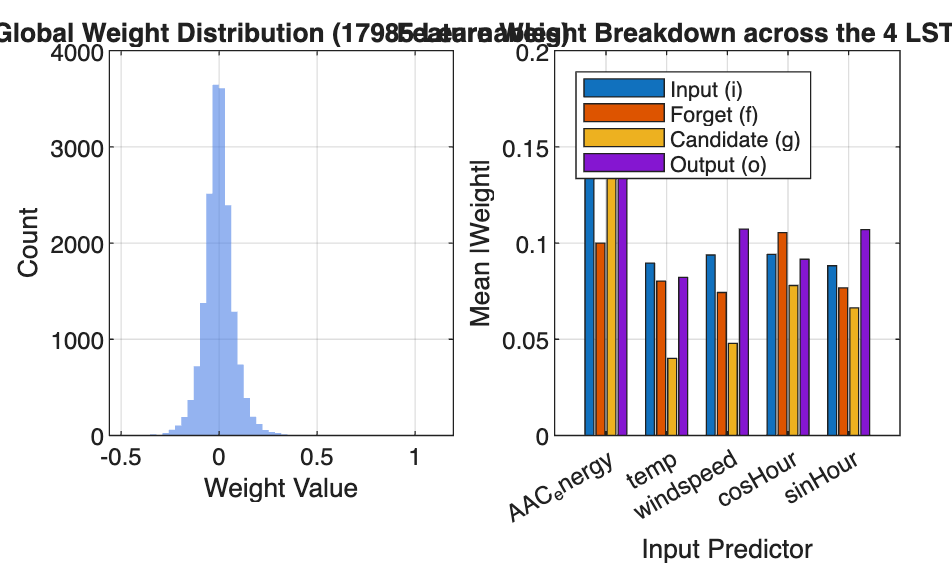

% Structural health check of all 17,985 trained weights
allWeights = [];
for p = 1:height(matNetFile.LSTMnet.Learnables)
    allWeights = [allWeights; extractdata(matNetFile.LSTMnet.Learnables.Value{p}(:))];
end

figure
tiledlayout(1, 2, Padding="compact", TileSpacing="compact")

% Left: Total weight density
nexttile
histogram(allWeights, 50, FaceColor=[0.3 0.5 0.9], EdgeColor="none")
title(sprintf("Global Weight Distribution (%d Learnables)", numel(allWeights)))
xlabel("Weight Value")
ylabel("Count")
grid on

% Right: Input weight magnitude per feature
nexttile
bar(categorical(matNetFile.predictorNames, matNetFile.predictorNames), [Wi', Wf', Wg', Wo'])
title("Feature Weight Breakdown across the 4 LSTM Gates")
xlabel("Input Predictor")
ylabel("Mean |Weight|")
legend(["Input (i)", "Forget (f)", "Candidate (g)", "Output (o)"], Location="northwest")
grid on